# Object Detection and Explainability with Imported TensorFlow Model

## Import and Initialize Network

Import a pretrained TensorFlow™ model for object detection. The model is in the SavedModel format.

modelFolder = "centernet_resnet50_v2_512x517_coco17";
detector = importNetworkFromTensorFlow(modelFolder);

Importing the saved model...
Translating the model, this may take a few minutes...
Import finished.


Specify the input size of the imported network. You can find the expected image size stated in the name of the TensorFlow network. The data format of the `dlarray` object must have the dimensions `"SSCB"` (spatial, spatial, channel, batch) to represent a 2-D image input. For more information, see [Data Formats for Prediction with dlnetwork](https://www.mathworks.com/help/deeplearning/ug/tips-on-importing-models-from-tensorflow-pytorch-and-onnx.html#mw_b48d26e1-7484-4802-aef3-502f61c36795). Initialize the imported network.

input_size = [512 512 3];
detector = detector.initialize(dlarray(ones(512,512,3,1),"SSCB"))

detector =   dlnetwork with properties:

         Layers: [1×1 centernet_resnet50_v2_512x517_coco17.kCall11498]
    Connections: [0×2 table]
     Learnables: [388×3 table]
          State: [0×3 table]
     InputNames: {'kCall11498'}
    OutputNames: {'kCall11498/detection_boxes'  'kCall11498/detection_classes'  'kCall11498/detection_scores'  'kCall11498/num_detections'}
    Initialized: 1

  View summary with summary.


Save the imported network, so you don't have to re-import the TensorFlow model if you want to run the following sections independently.

save("centernet_object_detector","detector","-v7.3")

## Detect with Imported Network

Optionally, load the imported network. The network has four outputs: bounding boxes, classes, scores, and number of detections.

%load("centernet_object_detector.mat")
mlOutputNames = detector.OutputNames'

mlOutputNames = 4×1 cell array
    {'kCall11498/detection_boxes'  }
    {'kCall11498/detection_classes'}
    {'kCall11498/detection_scores' }
    {'kCall11498/num_detections'   }


Read the image that you want to use for object detection. Perform object detection on the image.

img = imread("testCar.png");
[y1,y2,y3,y4] = detector.predict(dlarray(single(img),"SSCB"));

## Get Detections with Highest Scores

Create a map of all the network outputs.

mlOutputMap = containers.Map;
mlOutputs = {y1,y2,y3,y4};
for i = 1:numel(mlOutputNames)
    opNameStrSplit = strsplit(mlOutputNames{i},'/');
    opName = opNameStrSplit{end};
    mlOutputMap(opName) = mlOutputs{i};
end

Get the detections with scores above the threshold `thr`, and the corresponding class labels.

thr = 0.5;
[bboxes,classes,scores,num_box] = bestDetections(img,mlOutputMap,thr);
class_labels = getClassLabels(classes);

## Visualize Object Detection

Create the labels associated with each of the detected objects.

colons = repmat(": ",[1 num_box]);
percents = repmat("%",[1 num_box]);
labels = strcat(class_labels,colons,string(round(scores*100)),percents);

Visualize the object detection results with annotations.

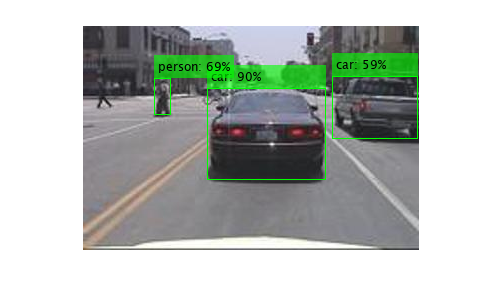

figure
outputImage = insertObjectAnnotation(img,"rectangle",bboxes,labels,LineWidth=1,Color="green");
imshow(outputImage)

## Explainability for Object Detector

Explain the predictions of the object detection network using D-RISE. Specify a custom detection function to use D-RISE with the imported TensorFlow Network.

targetBox = bboxes(1,:);
targetLabel = 1;
scoreMap = drise(@(img)customDetector(img),img,targetBox,targetLabel);

Plot the results.

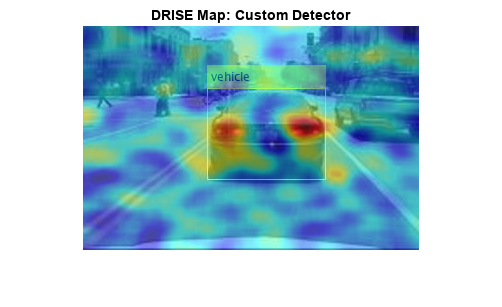

figure
annotatedImage = insertObjectAnnotation(img,"rectangle",targetBox,"vehicle");
imshow(annotatedImage)
hold on
imagesc(scoreMap,AlphaData=0.5)
title("DRISE Map: Custom Detector")
hold off
colormap jet